%{
Community Solar Billing Simulator Linear + Piecewise function
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Showcases how costly an electric bill would be depending on usage
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
Engineering Algorithms:
    - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding  
MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
%}
x=0:25:800

x =      0    25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500   525   550   575   600   625   650   675   700   725   750   775   800


planA= 15*x +25

planA =           25         400         775        1150        1525        1900        2275        2650        3025        3400        3775        4150        4525        4900        5275        5650        6025        6400        6775        7150        7525        7900        8275        8650        9025        9400        9775       10150       10525       10900       11275       11650       12025


planB = zeros(size(x))

planB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


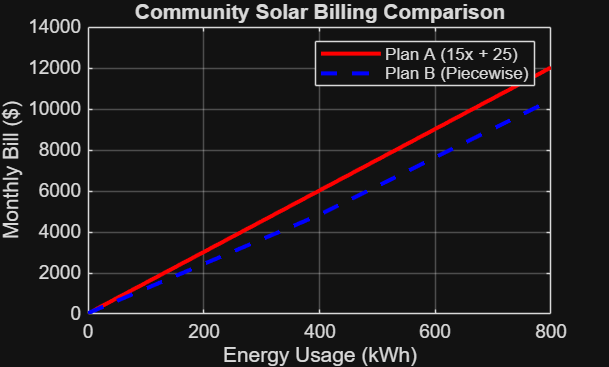

for i = 1:length(x)
    if x(i) <= 400
        planB(i) = 12*x(i) + 40;
    else
        planB(i) = 14*x(i) + (40 - 2 * 400);
    end
end

figure;
plot(x, planA, 'r', 'LineWidth', 2); hold on;
plot(x, planB, 'b--', 'LineWidth', 2);
grid on;

xlabel('Energy Usage (kWh)');
ylabel('Monthly Bill ($)');
title('Community Solar Billing Comparison');
legend('Plan A (15x + 25)', 'Plan B (Piecewise)');


%{
the customer should choose plan B as it has a lower monthly bill than plan
A does within the same amount of time. the slope for each plan is the
increase in cost for each plan, while the intercepts are the base cost for
each plan. the piecewise structure can change decision making as it is
possible that it wouldnt be straight and would eventually cost more that
plan A.
%}